# Segmenting Solar Flares

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

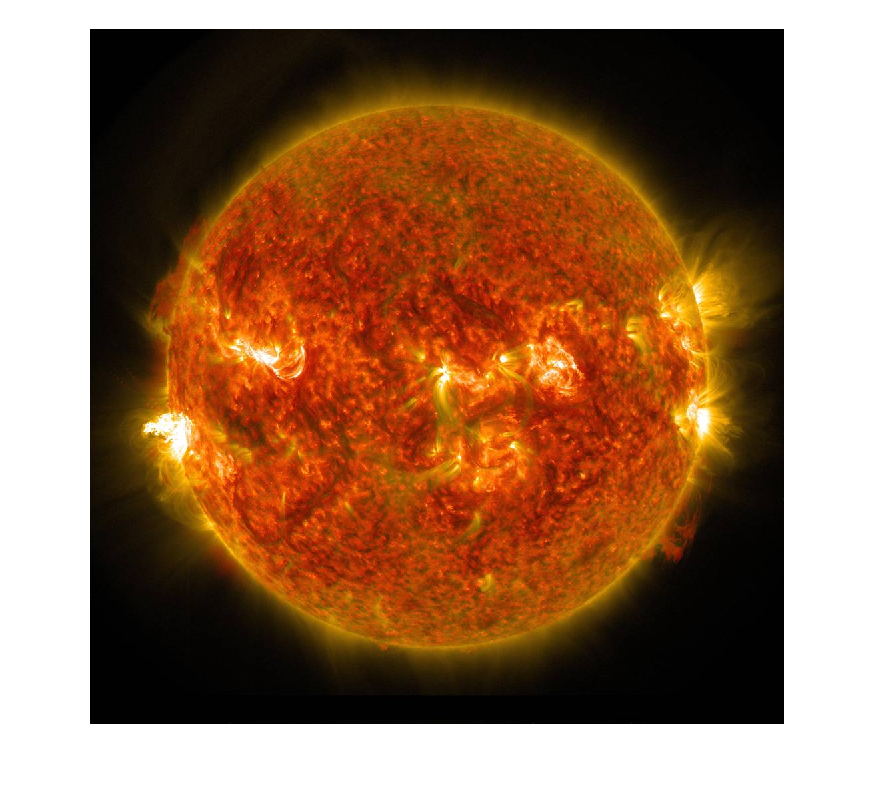

sf = imread("./images/solarFlare.jpg");
imshow(sf)

## Task 1

The function `rgb2hsv` converts an image from RGB to the HSV color space.

sfHSV = rgb2hsv(sf);

## Task 2

The `imsplit` function, which you used to extract the color planes from RGB images, can split other color spaces into their respective channels.

`[``ch1``,``ch2``,``ch3``]` `=` `imsplit``(``image``)``;`

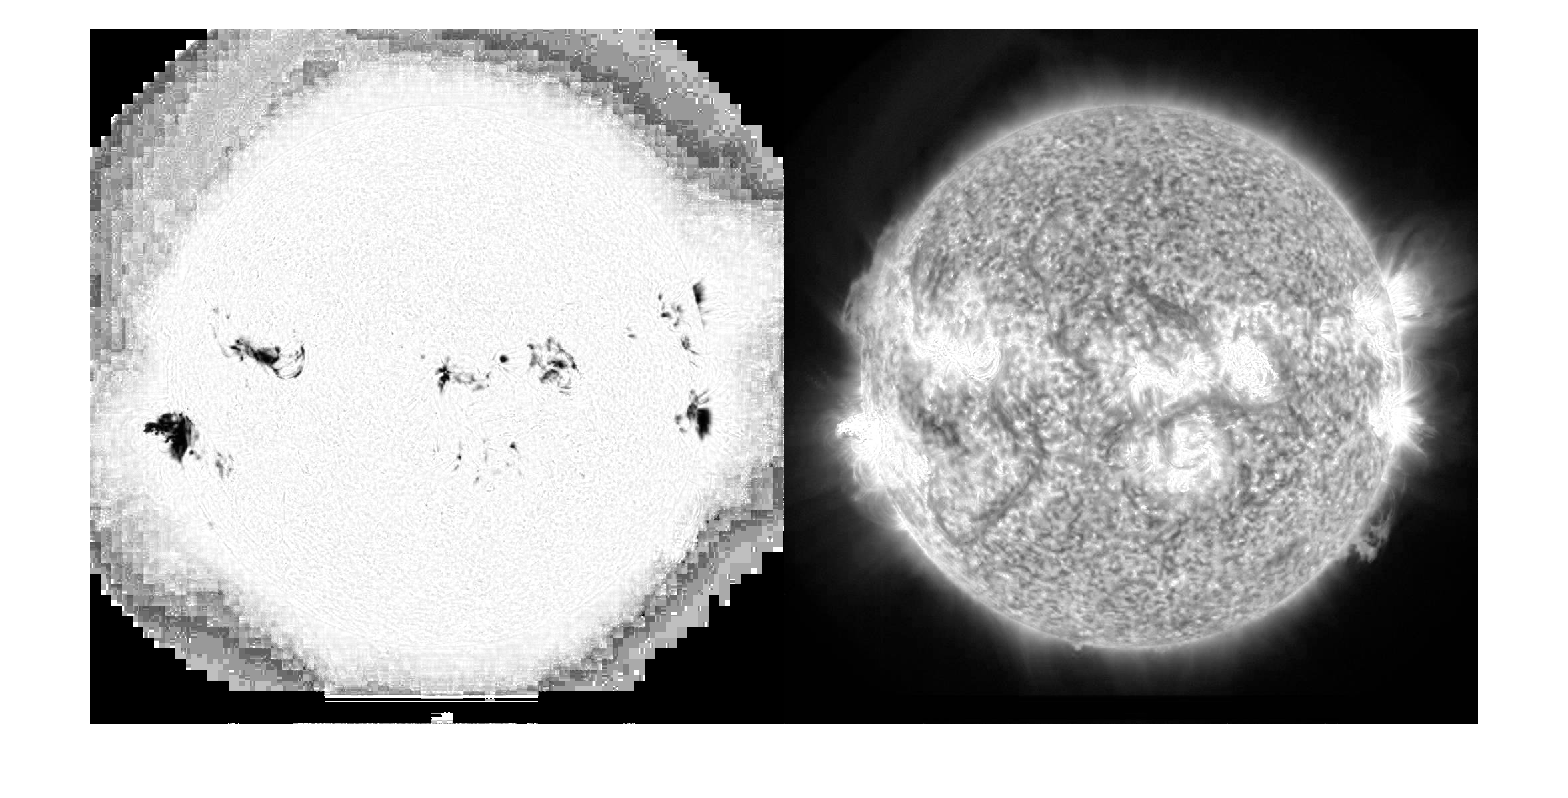

[h, s, v] = imsplit(sfHSV);
imshowpair(s, v, "montage")

## Task 3

Notice that the solar flares have low saturation and high value.

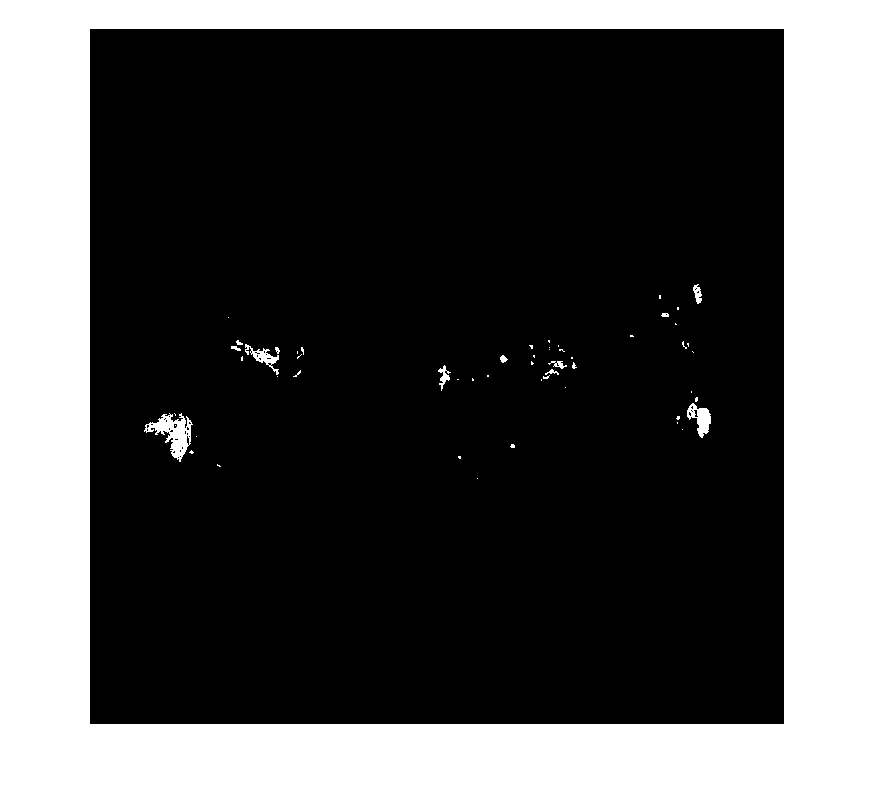

sfMask = (s < .5) & (v > .95);
imshow(sfMask)